# Computation of a linearly spaced set of points on a line

I've defined several usefull functions at the end of this "Matlab live script". These are:

- affine(): compute the slope and y-intercept of the regression line from a pair of points;

- angle(): compute the angle that this y = ax + b function forms with the abcissa;

- euclidist(): compute the euclidean distance between two points in an N-dimensional space;

## A set of two points is generated.

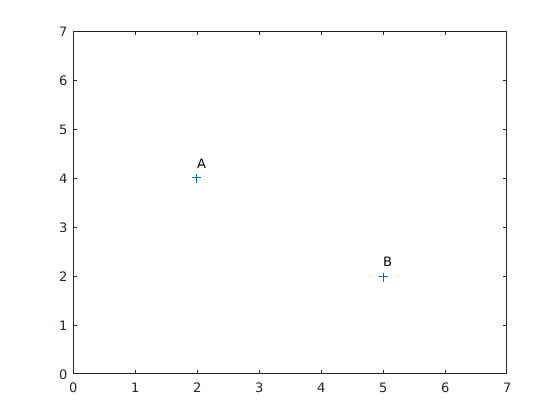

A = [2, 4];
B = [5, 2];

plot(B, A, '+');
xlim([0, 7]);
ylim([0, 7]);
text(A(1), A(2)+3/10, 'A');
text(B(1), B(2)+3/10, 'B');

[sl, yi] = affine(A, B)

sl = -0.6667

yi = 5.3333

## Euclidean distance

We compute the euclidean distance between the points, either by applying the pythagorean theorem, or by computing the $L^2$ norm (euclidean norm) of the difference between the vectors.

% Pythagorean theorem
ted = sqrt((B(1)-A(1))^2 + (B(2)-A(2))^2)

ted = 3.6056


% More general (also works in n-D spaces), L^2 norm / x1 and x2 must 
% be of the same size
ted = norm(B-A)

ted = 3.6056

## Determination of the corresponding function

Now we compute the y = ax + b formula by triangulation

slope = (B(2)-A(2)) / (B(1)-A(1));
slope

slope = -0.6667


yint = B(2) - slope * B(1);
yint

yint = 5.3333

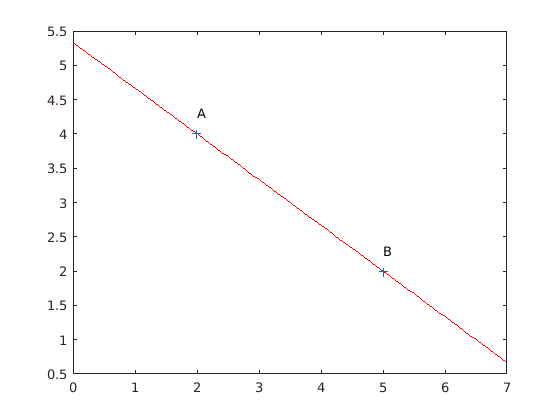


x = [0:0.1:7];
y = slope * x + yint;

plot(x, y, 'r');
hold('on');
plot(B, A, '+');
text(A(1), A(2)+3/10, 'A');
text(B(1), B(2)+3/10, 'B');
hold('off')

We then need trigonometry to find the angle that y = ax+b corresponds to with respect to the horizontal axis and to compute resp. the sin() and cos() of the angle to get the coordinates. The arctan of the slope provides the angle (in radians) that the line forms with the abcissa.

theta = atan(slope);

Then we can compute the coordinates of a point on this line on the basis of the distance between the reference point and the expected point along the corresponding vector. To do this, we use trigonometric properties of the angle that is formed by the the line with the horizontal axis:


$$x_k = x_0 + (d * cos(\theta))\\
y_k = y_0 + (d * sin(\theta))
$$


With ($x_0$, $y_0$) the coordinates of the reference point, $\theta$ the angle that is formed by the line with respect to the horizontal axis, and ($x_k$, $y_k$) the resulting coordinates of the point. We can apply it directly on a vector of distances and an angle in radians in Matlab. We start by defining the vector of distances (`dvect`).

nbpoints = 10;
dvect = linspace(0, ted, nbpoints);

The `dvect` vector is defined as a linearly spaced vector of distances whose values depend on the larger distance between two points and the total number of points we wish to obtain. $\theta$ is the vector angle in radians. `A` is the reference point defined by a vector of coordinates. The resulting coordinates are:

X = A(1) + (dvect * cos(theta));
Y = A(2) + (dvect * sin(theta));

dvect

dvect =          0    0.4006    0.8012    1.2019    1.6025    2.0031    2.4037    2.8043    3.2049    3.6056


X

X =     2.0000    2.3333    2.6667    3.0000    3.3333    3.6667    4.0000    4.3333    4.6667    5.0000


Y

Y =     4.0000    3.7778    3.5556    3.3333    3.1111    2.8889    2.6667    2.4444    2.2222    2.0000


One can compare with the coordinates that would be obtained by simply computing coordinates from distances on the axes:

Xalt = linspace(A(1), B(1), nbpoints);
Yalt = linspace(A(2), B(2), nbpoints);

Xalt

Xalt =     2.0000    2.3333    2.6667    3.0000    3.3333    3.6667    4.0000    4.3333    4.6667    5.0000


Yalt

Yalt =     4.0000    3.7778    3.5556    3.3333    3.1111    2.8889    2.6667    2.4444    2.2222    2.0000


It's strictly the same. Only with a curve would the coordinates differ...

# Formant manipulation

Now, we'll work with a series of formant frequencies in Hz: The process is the following:

- Convert the point frequencies to Bark;

- Generate a series of linearly spaced coordinates in the Bark domain;

- Convert them back to Hz;

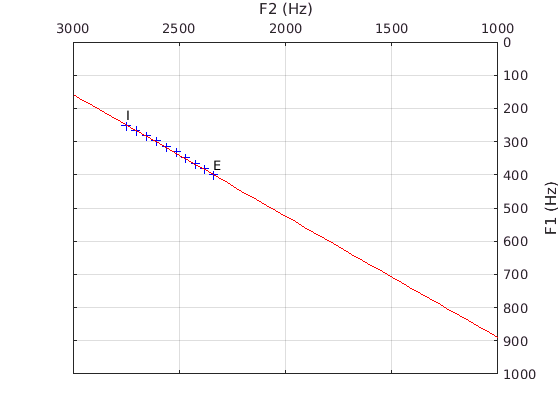

I = [250, 2750];
E = [400, 2340];

Iz = f2Bark(I);
Ez = f2Bark(E);

% Simple method
Xzalt = linspace(Iz(1), Ez(1), nbpoints);
Yzalt = linspace(Iz(2), Ez(2), nbpoints);

Xalt = f2Bark(Xzalt, 'back');
Yalt = f2Bark(Yzalt, 'back');
%Xalt = 1960 ./ (26.81 ./ (Xzalt + 0.53) - 1);
%Yalt = 1960 ./ (26.81 ./ (Yzalt + 0.53) - 1);

%Xalt
%Yalt

plot(Yalt, Xalt, 'b+');
text(I(2), I(1)-300/10, 'I');
text(E(2), E(1)-300/10, 'E');
xlabel('F2 (Hz)');
ylabel('F1 (Hz)');
set(gca,'XDir','Reverse')
set(gca,'YDir','Reverse')
set(gca, 'XAxisLocation', 'top'),
set(gca, 'YAxisLocation', 'right'),
xlim([1000, 3000]);
ylim([0, 1000]);
grid('on');

% In order to compute the corresponding linear function, we need to flip 
% the coordinates as we work with F1 (y-axis) ~ F2 (x-axis) data whereas 
% the data points are associated with (F1 = x-axis, F2 = y-axis) values.
[sl, yi] = affine(flip(E), flip(I));
%x = linspace(1000, 3000, 100);
hold('on');
fplot(@(x) sl .* x + yi, 'r');
hold('off');

It is obvious that returning back to the Hz scale does not produce a strict linear relation between the points. How important is this? It is expected as the relation between the Hertz and Bark scales is non-linear. Also, it has implications concerning the appropriate method to generate the sequence of points along the frequency scale. Using a distance-based sequencing is clearly better according to this point because there won't be a linear spacing of points along a curve if we work based on a linear spacing on the orthogonal dimensions.

An alternate method computing distances on the line Is it actually possible to work like this as there may be issues with starting from a high frequency vs. a low frequency in the Bark domain.: Moreover, it is in this case implied that the change from I won't be linear with the change from E in reversed direction...

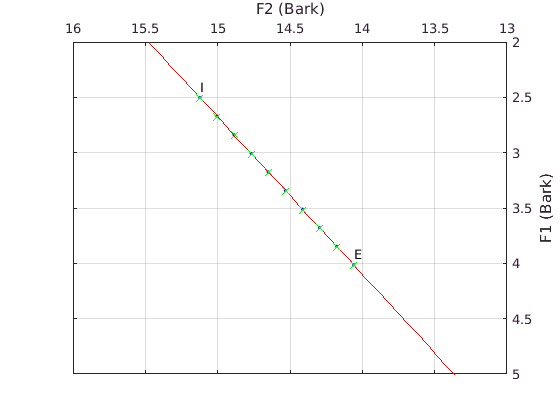

% We work in the Bark domain

% First we define the euclidean distance vector between points
ed = euclidist(Iz, Ez); % internal function
nbpoints = 10;
dvect = linspace(0, ed, nbpoints);

% Then we compute the y = ax + b equivalent function between the 
% two endpoints
[sl, yi] = affine(Iz, Ez); % internal function

% Finally, we generate the sequence of linearly spaced
% points between the endpoints
[coords, theta] = lpoints(Iz, dvect, sl);
%[coords, theta] = lpoints(Ez, -dvect, sl);

% The Bark coordinates are then converted back to Hertz coordinates
freqs = f2Bark(coords, 'back');

% Plots in the Bark domain (reference = points generated
% on the orthogonal dimensions). We compare with the simple approach.
plot(Yzalt, Xzalt, 'b.');
text(Iz(2), Iz(1)-1/10, 'I');
text(Ez(2), Ez(1)-1/10, 'E');
xlabel('F2 (Bark)');
ylabel('F1 (Bark)');
set(gca,'XDir','Reverse');
set(gca,'YDir','Reverse');
set(gca, 'XAxisLocation', 'top');
set(gca, 'YAxisLocation', 'right');
xlim([13, 16]);
ylim([2, 5]);
grid('on');

% In order to compute the function for display we need to flip the 
% coordinates as we work with F1 (y-axis) ~ F2 (x-axis) data 
% whereas the points are associated with (F1 = x-axis, F2 = y-axis) values.

% Linear function based on the two original endpoints
[sl, yi] = affine(flip(Iz), flip(Ez));

% Linear function based on distance along the line
[sl, yi] = affine(flip(coords(:,1)), flip(coords(:,nbpoints)));

% Drawing
hold('on');
fplot(@(x) sl .* x + yi, 'r');
% We plot F1 ~ F2 (F2 = X, F1 = Y)
plot(coords(2,:), coords(1, :), 'gx');
hold('off');

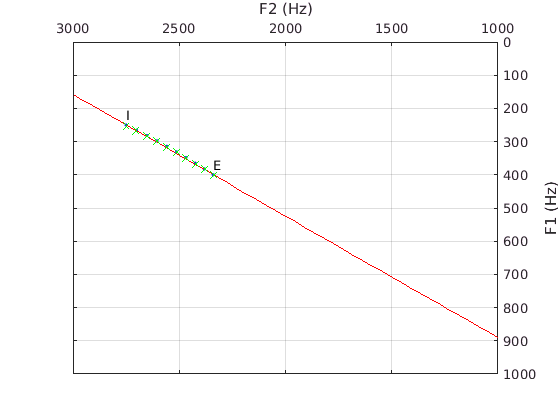



% Plots in the Hertz domain

plot(Yalt, Xalt, 'b.');
text(I(2), I(1)-300/10, 'I');
text(E(2), E(1)-300/10, 'E');
xlabel('F2 (Hz)');
ylabel('F1 (Hz)');
set(gca,'XDir','Reverse')
set(gca,'YDir','Reverse')
set(gca, 'XAxisLocation', 'top'),
set(gca, 'YAxisLocation', 'right'),
xlim([1000, 3000]);
ylim([0, 1000]);
grid('on');

% We need to flip the coordinates as we work with F1 (y-axis) ~ F2 (x-axis) data 
% whereas the points are associated with (F1 = x-axis, F2 = y-axis) values.
%[sl, yi] = affine(flip(I), flip(E));

% Linear function based on F1~F2 orthogonal sequence
%[sl, yi] = affine(flip(Iz), flip(Ez));

% Linear function based on distance along the line
[sl, yi] = affine(flip(freqs(:,nbpoints)), flip(freqs(:,1)));

%x = linspace(1000, 3000, 100);
hold('on');
fplot(@(x) sl .* x + yi, 'r');
% We plot F1 ~ F2 (F2 = X, F1 = Y)
plot(freqs(2,:), freqs(1, :), 'gx');
hold('off');


%freqs


## Solving systems of linear equations using Matrix notation

    A = [1, 6, 3];
    B = [8, 2, 7];
    B-A

ans =      7    -4     4


Let's say we have the following equations that have already been defined:

2x + 0y - 1z = 2 (equivalent to 2x - z = 2)

0x + 2y -2z = 1 (equivalent to 2y -2z = 1)

In Matlab / Octave, it will be processed in Matrix form:

P = [2, 0, -1; 0, 2, -2] % Parameters

P =      2     0    -1
     0     2    -2


r = [2; 1] % results

r =      2
     1


P\r % solving the system of linear equations

ans =     0.7500
         0
   -0.5000


## These results may be interpreted in which sense?

0.75x -0.5z = 0

r*

## Function definitions

function [slope, yint] = affine(A, B)
    slope = (B(2)-A(2)) / (B(1)-A(1));
    yint = B(2) - slope * B(1);
end

function edist = euclidist(A, B)
    edist = norm(B - A);
end

function [coords, theta] = lpoints(refpoint, distance, slope)
    % refpoint must be have its coordinates in a 2D space
    dim = size(refpoint);
    theta = atan(slope);
    X = refpoint(1) + (distance * cos(theta));
    Y = refpoint(2) + (distance * sin(theta));
    if (dim(2) > 1)
        coords = [X; Y];
    elseif (dim(1) > 1)
        coords = [X, Y];
    end
end

function output = f2Bark(input, inv)
    if nargin < 2
        inv = false;
    else
        inv = true;
    end
    if (~inv)
        output = (26.81 ./ (1 + 1960 ./ input )) - 0.53;
    else
        output = 1960 ./ (26.81 ./ (input + 0.53) - 1);
    end
end
